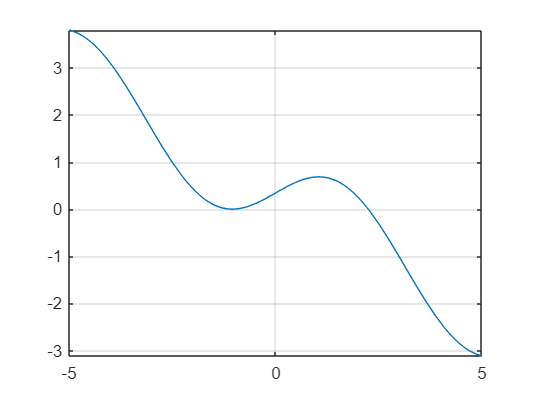

%% Oefening 4.18
clear all; close all; clc; format long

g = @(x) sin(x) -x/2 -pi/6 + sqrt(3)/2;
fplot(g)
grid on

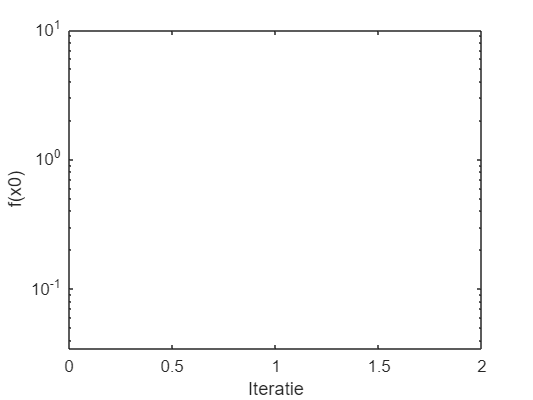

toleration: 100
Iterations: 1
Theory?: 0


a = -4;
b = 4;
tol = 10^-10;
nmax = 100;
x0 = -pi/2;
res_1 = bisection(g,a,b,nmax,tol, false);

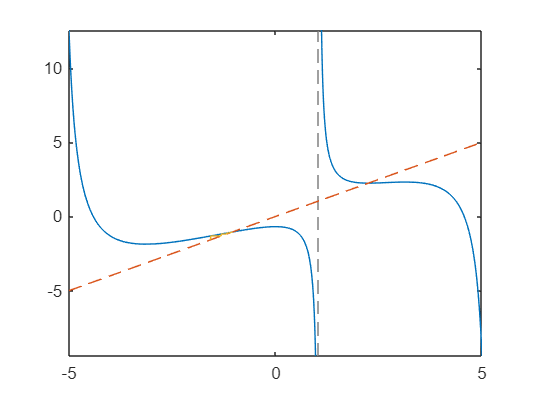

toleration: 1e-10
Iterations: 17


res_2 =   -1.047206078066725


res_2 = newton(g,x0,tol,nmax)

res_3 = newton_adapt(g,x0,tol,nmax)

iteraties =      3


waarde =   -1.047211902180479


res_3 =   -1.570796326794897  -1.059497160460544  -1.047211902180479


function [res] = newton_adapt(f,x0,tol,nmax)

    if abs(f(x0))<tol % de gekozen startwaarde is al een nulpunt van de functie
        res = x0;
        return
    else
        % iteratief proces
        res = zeros(1,nmax); % op voorhand een grootte toekennen aan res-vector
        res(1) = x0; % eerste waarde fixeren
        
        %Afgeleide symbolisch voorstellen
        syms x
        g = matlabFunction(x-2*f(x)/diff(f(x),1)); % Converteer symbolic expression naar function handle of file
        for i = 2:nmax
            res(i) = g(res(i-1)); % nieuwe waarde
           if abs(f(res(i))) < tol %stopvoorwaarde
               iteraties = i
               waarde = res(i)
               break
           end
        end
        format long
        res = res(1:i); % enkel de waarden weergeven die gebruikt zijn 
    end
end